# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396

## **Punto 1**

Se implementan las señales x(t) y y(t) de la envolvente compleja para una modulación 8PSK con un tiempo de 0.05 segundos, para transmitir la secuencia de bits 101100111001 (asumiendo que se transmiten de derecha a izquierda). El diagrama de constelación sugerido es el siguiente:

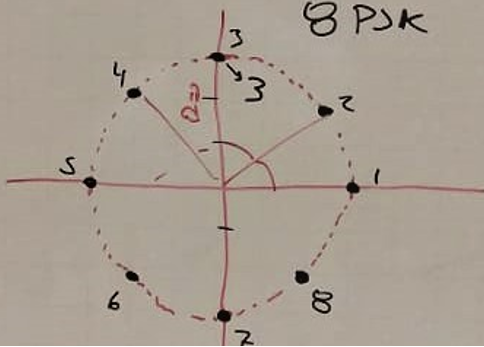

Inicialmente, se definen ciertos parámetros importantes para este procedimiento, encontrando así el tiempo de bit, el número de bits por símbolo (L), el número de muestras por símbolo, el periodo y la frecuencia de muestreo, además de la amplitud y la frecuencia de la portadora.

clear all; clc; %Limpiar variables anteriores

Tb = 0.05;      %Tiempo de Bit
M = 8;          %# de símbolos posibles
L = log2(M);    %# de Bits que conforman un Símbolo
sps = 16;       %Muestras por símbolo

Ts = Tb/sps;    %Tiempo de Muestreo
fs = 1/Ts;      %Frecuencia de Muestreo

Ac = 1;         %Amplitud Portadora
fc = fs/8;      %Frecuencia de portadora 

En este caso, se fijan el valor del tiempo de bit, de *M* y de *L *justo como fue indicado en el enunciado del ejercicio, después, se define *sps* como 16 muestras por símbolo, lo que hace que la frecuencia de muestreo sea mayor al límite de Nyquist por un margen considerable, logrando así un sobremuestreo de la señal que facilita su posterior visualización. Finalmente, para la amplitud de la portadora se escogió arbitrariamente una magnitud de 1, pues como se modula fase esta variable no debería afectar el análisis a realizar, además, se definió la frecuencia de la portadora como un octavo de la de muestreo.

Teniendo esto en cuenta se continuó incluyendo la variable de los bits de llegada, además de otras variables que se utilizarán más tarde.

bits = [1 0 1 1 0 0 1 1 1 0 0 1];                %Bits de llegada
NBit = length(bits);                             %Número de Bits 
Nsamples = NBit*sps;                             %Número de Muestras

Después, se realizó el empaquetamiento de los bits para determinar los símbolos de entrada, esto se logró con la función *bit2sym *definida por los autores de este documento en la parte final de este.

[sym, bits] = bit2sym(bits,L);                           %Símbolos en la salida
sym

sym =      1     7     4     5


Después, se constituyó la señal de información $m\left(t\right)$ y una multinivel que representa los símbolos llamada $\textrm{sym}\left(t\right)$. Para esto, fue necesario obtener cada bit o símbolo y replicarlo el número de muestras respectivo, esto se hizo con la función *vect2samp* también definida al final del script:

m_t = vect2samp(bits,sps);                       %Señal de información en el tiempo
sym_t = vect2samp(sym, sps*L);                   %Señal multinivel

Ya con todo esto realizado, se usaron las fórmulas aprendidas en clase para obtener la envolvente compleja para este tipo de modulación, además de sus dos componentes real e imaginario junto con el resultado de la modulación $s\left(t\right)$.

t = 0:Ts:Tb*NBit-Ts;                             %Tiempo
g_t = Ac*exp(1j*sym_t*pi/4);                     %Envolvente compleja
x_t = real(g_t);                                 %Componente en Fase
y_t = imag(g_t);                                 %Componente en cuadratura
s_t = x_t.*cos(2*pi*fc*t)-y_t.*sin(2*pi*fc*t);   %Señal Modulada

Para lograr visualizar los resultados obtenidos, se realizará la gráfica de los dos componentes de la envolvente compleja, además de la señal final $s\left(t\right)$. De esta forma, se observó primero la componente en fase:

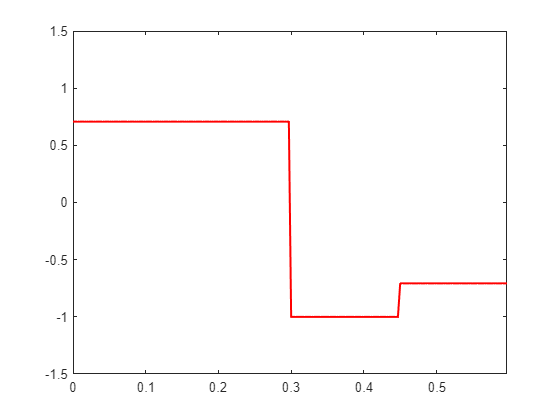

plot(t,x_t,'color','r','linewidth',1.5)
xlim([0 Tb*NBit-Ts])
ylim([-1.5 1.5])

Se puede ver que la señal x(t) puede tomar 5 valores diferentes, asociados a cada posición del diagrama de constelación mostrado en el documento guía.


$$x\left(t\right)=\left\lbrack \begin{array}{cc}
1 & ,\;\textrm{para}\;\textrm{la}\;\textrm{posición}\;1\;\textrm{del}\;\textrm{diagrama}\\
\frac{1}{\sqrt{2}} & ,\;\textrm{para}\;\textrm{las}\;\textrm{posiciones}\;2\;y\;8\;\textrm{del}\;\textrm{diagrama}\\
0 & ,\;\textrm{para}\;\textrm{las}\;\textrm{posiciones}\;\;3\;y\;7\;\textrm{del}\;\textrm{diagrama}\\
-\frac{1}{\sqrt{2}} & ,\;\textrm{para}\;\textrm{las}\;\textrm{posiciones}\;4\;y\;6\;\;\textrm{del}\;\textrm{diagrama}\\
-1 & ,\;\textrm{para}\;\textrm{la}\;\textrm{posición}\;5\;\;\textrm{del}\;\textrm{diagrama}
\end{array}\right\rbrack$$


De la misma forma la gráfica de la señal y(t) también se aprecia que toma diferentes valores dependiendo de la posición en el diagrama de constelaciones.

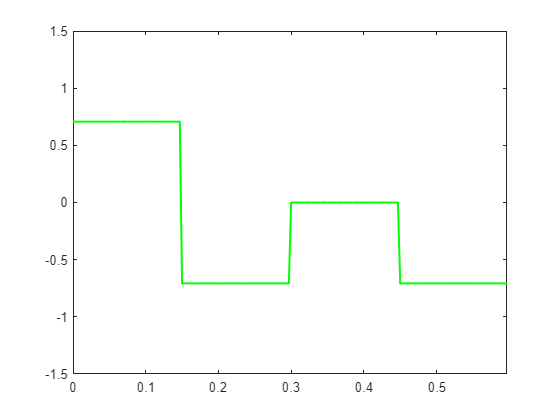

plot(t,y_t,'color','g','linewidth',1.5)
xlim([0 Tb*NBit-Ts])
ylim([-1.5 1.5])

Al igual que con el componente en fase, la señal y(t) puede tomar 5 valores diferentes, asociados a cada posición del diagrama de constelaciones mostrado en el documento guía.


$$y\left(t\right)=\left\lbrack \begin{array}{cc}
0 & ,\;\textrm{para}\;\textrm{las}\;\textrm{posiciones}\;\;1\;y\;5\;\textrm{del}\;\textrm{diagrama}\\
\frac{1}{\sqrt{2}} & ,\;\textrm{para}\;\textrm{las}\;\textrm{posiciones}\;2\;y\;4\;\textrm{del}\;\textrm{diagrama}\\
1 & ,\;\textrm{para}\;\textrm{la}\;\textrm{posición}\;3\;\textrm{del}\;\textrm{diagrama}\\
-\frac{1}{\sqrt{2}} & ,\;\textrm{para}\;\textrm{las}\;\textrm{posiciones}\;6\;y\;8\;\;\textrm{del}\;\textrm{diagrama}\\
-1 & ,\;\textrm{para}\;\textrm{la}\;\textrm{posición}\;7\;\;\textrm{del}\;\textrm{diagrama}
\end{array}\right\rbrack$$


Finalmente se mostrará la gráfica de la señal modulada s(t):

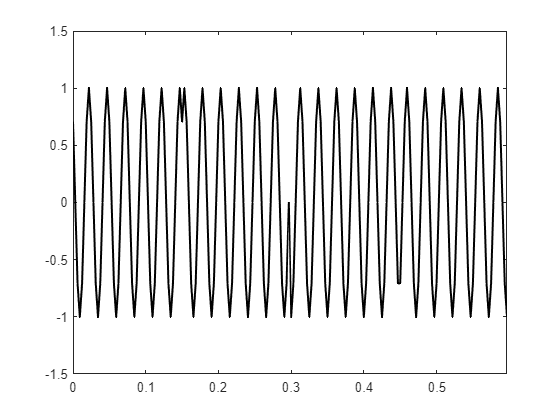

plot(t,s_t,'color','black','linewidth',1.5)
xlim([0 Tb*NBit-Ts])
ylim([-1.5 1.5])

En ella es posible apreciar que la señal $s\left(t\right)$ sufre cambios bruscos de fase cuanto $t$ es igual a 0.15, 0.3 y 0.45, lo cual es provocado por los cambios en los componentes en fase y cuadratura antes vistos: en el primer cambio se evidencia que la onda seno "rebota", mientras que en el segundo esta baja repentínamente y en el último caso, al haber una transición entre 2 símbolos cercanos (4 y 5) no se tiene un salto tan grande como los otros. De esta forma, si se obtiene la gráfica de las 3 señales anteriores más el mensaje, se podrá verificar que estos saltos coinciden:

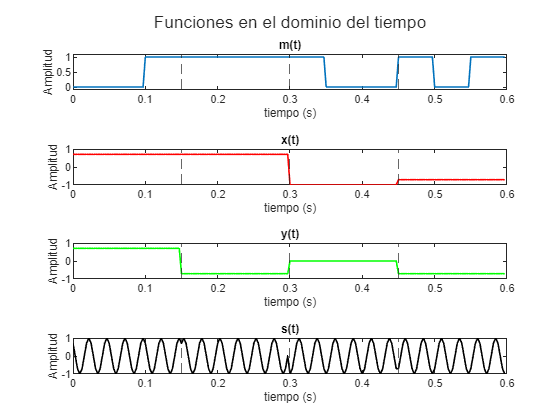

p = tiledlayout(4,1);
title(p,"Funciones en el dominio del tiempo")

nexttile; plot(t,m_t,'LineWidth',1.2); title("m(t)"); 
xline(0.15,'--'); xline(0.3,'--'); xline(0.45,'--');
ylabel("Amplitud"); xlabel("tiempo (s)"); ylim([-0.1, 1.1]);

nexttile; plot(t,x_t,'red','LineWidth',1.2); title("x(t)"); 
xline(0.15,'--'); xline(0.3,'--'); xline(0.45,'--');
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,y_t,'green','LineWidth',1.2); title("y(t)"); 
xline(0.15,'--'); xline(0.3,'--'); xline(0.45,'--');
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,s_t,'black','LineWidth',1.2); title("s(t)"); 
xline(0.15,'--'); xline(0.3,'--'); xline(0.45,'--');
ylabel("Amplitud"); xlabel("tiempo (s)");

Claramente, se puede detallar que la duración de los símbolos es de 0.15 [s], esto debido a que cada bit dura exactamente 0.05 [s] y 3 de estos conforman un símbolo. Además, se verifica la correcta correspondencia entre el símbolo y los valores de $x\left(t\right)$ y $y\left(t\right)$ esperados, por ejemplo, en el primer símbolo se tiene un "001", por lo que corresponderá a la segunda posición, entonces:

$x\left(t\right)=\cos \left(\frac{\pi \;}{4}*1\right)=\frac{1}{\sqrt{2}}$  y  $y\left(t\right)=\sin \left(\frac{\pi \;}{4}*1\right)=\frac{1}{\sqrt{2}}$

Buscando este instante en la anterior gráfica confirma que tanto el componente en fase como el de cuadratura tienen magnitudes iguales al inverso de la raíz de 2.

Después, se pasó al dominio de la frecuencia, obteniendo el espectro de la señal mensaje $m\left(t\right)$, de la envolvente compleja $g\left(t\right)$ y de la modulación final $s\left(t\right)$ con la función *fft, *además, se usó *fftshift* para hacer que el espectro se centrara sobre 0:

n = length(t);
f = (-n/2:n/2-1)*(fs/n);
m_f = fftshift(fft(m_t));
g_f = fftshift(fft(g_t));
s_f = fftshift(fft(s_t));

Realizando la gráfica de las 3 funciones:

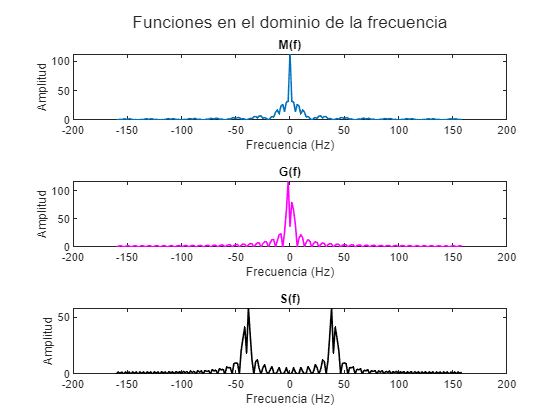

q = tiledlayout(3,1);
title(q,"Funciones en el dominio de la frecuencia")

nexttile; plot(f,abs(m_f),'LineWidth',1.2); title("M(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")

nexttile; plot(f,abs(g_f),'magenta','LineWidth',1.2); title("G(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")

nexttile; plot(f,abs(s_f),'black','LineWidth',1.2); title("S(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")

Del primer espectro, se tiene un pico que sobresale en la frecuencia nula o DC (en 0 Hz) pues la señal, al ser de tipo polar únicamente tendrá como valor 1 o 0, por lo que existirá un valor medio que se verificará en el espectro. Al alejarse del eje, se presenta una forma similar a una función *sinc, *teniendo una serie de oscilaciones cuya amplitud empieza a atenuarse conforme la magnitud de la frecuencia aumenta. Estos lobulos tocan cero en frecuencias múltiplos de 20[Hz], siendo igual a la tasa de transmisión de bits:


$$R_b =\frac{1}{0\ldotp 05}=20\left\lbrack \textrm{Hz}\right\rbrack$$


Pasando ahora a la envolvente compleja, se presenta una vez más el espectro de una señal de tipo *sinc *siendo bastante similar al del caso anterior. No obstante, ahora se evidencia una pareja de picos que hacen que la señal no sea par, lo cual sucede pues la envolvente compleja $g\left(t\right)\;$ya no es una señal real sino una compleja, por lo que esta propiedad se pierde. Otra cuestión a resaltar es el ancho de los lóbulos, los cuales son más cortos que antes pues el ancho de los pulsos se triplicó, debido a que ahora la señal depende del tiempo de símbolo y no de bits.

Finalmente, en la representación frecuencial de $s\left(t\right)$ se tienen dos copias del espectro de la envolvente compleja, esto debido a que por definición esta señal cumple lo siguiente:


$$s\left(t\right)=x\left(t\right)\cos \left(2\pi f_c t\right)-y\left(t\right)\sin \left(2\pi f_c t\right)$$


Por lo que su espectro dependerá del de la envolvente compleja, existiendo desfases debido a las dos funciones trigonométricas. Además, se presenta una atenuación de la mitad de la amplitud, que se puede verificar observando la escala vertical, pasando de 100 en $g\left(t\right)$ a 50 en esta señal. También, cabe notar que se recupera la paridad de la transformada de fourier debido a que su representación temporal volvió a ser completamente real.

A continuación, se pueden observar las 2 funciones personalizadas que se usaron:

function [sym, bitOrder] = bit2sym(bits, L) %Para generar los símbolos
    NBit = length(bits);
    Power2 = 2.^(L-1:-1:0);
    Nsteps = NBit/L;
    sym = zeros(1,Nsteps);
    for i = 1:Nsteps
        BitAct = bits(end-i*L+1:end-(i-1)*L);
        bitOrder(1+(i-1)*L:i*L) = BitAct;
        sym(i) = dot(Power2,BitAct);
    end
end

function m = vect2samp(vect, sps) %Para pasar de los bits al tiempo muestreado
    Nvect = length(vect);
    m = zeros(1, sps*Nvect);
    for i = 1:Nvect
        m((i-1)*sps+1:i*sps) = vect(i);
    end
end